# Controlling the Position

Now that the Attitude Controller gains are tuned, we can control the attitude of our multirotor to move it around. For this purpose, we have a Position Controller module which takes the desired position and yaw and does two things:

- Calculates the desired attitude (roll, pitch and yaw) for the Attitude Controller.

- Calculates some acceleration command that will move the multirotor to the desired position.

In this task, first, you will calculate the desired attitude from a given acceleration and desired yaw and then you will implement a PID loop for the Position Controller. Finally, you will tune the gains for your newly written controller.

*Note that you need to run *`task1.mlx`* first before being able to work on this task. Just run it first with your final PID gains if you have not done so yet.*

## Calculating the Attitude

Let's start with calculating the attitude for our Attitude Controller module to control. Assuming that we have the desired acceleration (in global frame) and the desired yaw (in degrees), we know that the multirotor should tilt in a way that the total generated thrust aligns with its Z axis. So, first we need to obtain the thrust direction from the acceleration command by adding the gravity to it:


$$\vec{T} = \vec{a}_{cmd} + \vec{g}$$


We are using FRD (Forward-Right-Down) frame for the robot. Therefore, the Z axis can be simply extracted from the thrust as:


$$\hat{z} = \frac{\vec{T}}{\|\vec{T}\|$$


To get the X axis, we can find the right side direction on the horizontal plane and find the vector normal to the right side and the Z axis:


$$\hat{x} = \frac{ 
\left[\matrix{ -\sin\psi_{des} \cr \cos \psi_{des} \cr 0} \right]
\times \hat{z}}{\left\| 
\left[\matrix{ -\sin\psi_{des} \cr \cos \psi_{des} \cr 0} \right]
\times \hat{z}\right\|}$$


Now, Y axis can be calculated from the Z and X axes:


$$\hat{y} = \hat{z} \times \hat{x}$$


We already know the yaw and only need the roll and pitch. Try to find the roll and pitch from the axes. You can draw the axes on a piece of paper and use trigonometry to get the roll and pitch. Or you can use matlab functions or search on the internet.

### Task 2.1 

Let's code it all. **Open "**`task2_calc_attitude.m"`** file and complete the code.**

Let's test if the code works by testing a few inputs and compare with the expected outputs: 

% Command                                   % Expected approximate result
a1 = task2_calc_attitude([0; 0; 0], 0)'           % [ 0      0     0  ]

a1 =      0     0     0


a2 = task2_calc_attitude([0; 0; 5], 30)'          % [ 0      0     30 ]

a2 =      0     0    30


a3 = task2_calc_attitude([10; 0; 0], 0)'          % [ 0      45.6  0  ]

a3 =          0   45.5593         0


a4 = task2_calc_attitude([0; 10; 0], 0)'          % [ -45.6  0     0  ]

a4 =   -45.5593         0         0


a5 = task2_calc_attitude([10; 0; 0], 30)'         % [ 20.9   41.5  30 ]

a5 =    20.9153   41.4477   30.0000


a6 = task2_calc_attitude([0; 10; 0], 30)'         % [ -38.2  27.0  30 ]

a6 =   -38.1936   27.0151   30.0000


a7 = task2_calc_attitude([10; 0; 20], 30)'        % [ 9.2    16.2  30 ]

a7 =     9.1510   16.2011   30.0000


a8 = task2_calc_attitude([10; 20; 0], 30)'        % [ -30.3  62.3  30 ]

a8 =   -30.3045   62.2764   30.0000


a9 = task2_calc_attitude([10; 20; 30], 30)'       % [ -15.7  25.1  30 ]

a9 =   -15.6553   25.1159   30.0000


If everything looks good, we are ready to implement the Position PID controller!

## Calculating the Acceleration

Now is the time to complete the Position Controller. As mentioned, the output acceleration is calculated using PID gains on the position and velocity errors:


$$\vec{a}_{cmd} = P \cdot e(t) + I \cdot \int_0^t e(t')dt' + D \cdot \dot{e}(t)$$


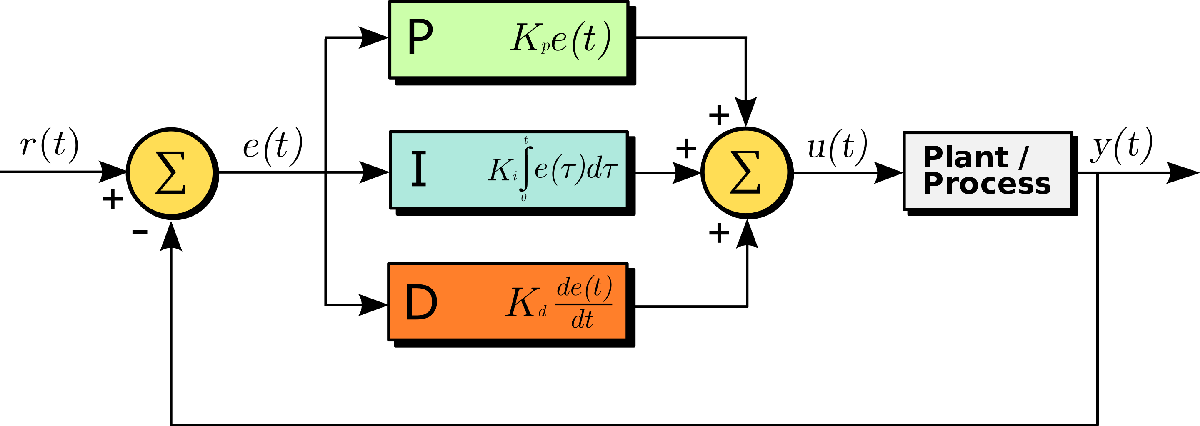

In our case, we can calculate the error term `e(t)` as the difference between desired position and the current position. For the derivative term, we can assume that our desired velocity is zero and calculate the velocity error based on that. For the integral term you need to keep the track of the position error integral and update it appropriately similar to this code:

### Task 2.2

Let's implement a PID controller. **Open "**`task2_calc_acceleration.m"`** file and complete the code.**

After finishing the implementation, your position controller, and in fact, your whole multirotor is complete!!!

To test the implemented code let's set the initial conditions for the multirotor (a reminder that the inputs are (`pos, vel, rpy, omega)`):

sim.Multirotor.SetInitialState([30; 20; 10], zeros(3, 1), [0; 0; 10], zeros(3, 1));

Let's see the response for a position command now (the first input is the acceleration and the second input is the desired yaw):

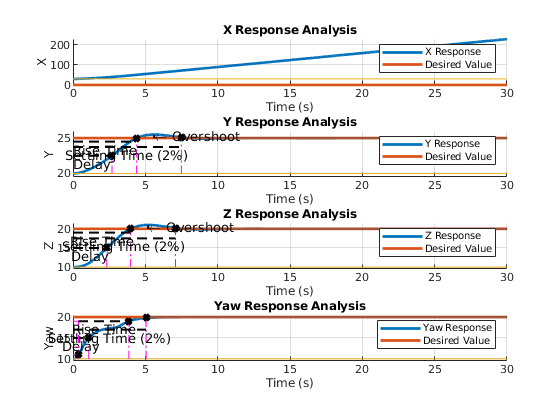

Analysis for response of X going from 30.00 to 0.00:
    Total Simulation Time: 30.000 (s)
    Simulation Time Step : 1.00 (ms)
    The system type is   : Overdamped
    Fall Time (10%-90%)  : 0.000 (s)
    Delay Time (0%-50%)  : 0.000 (s)
    Settling Time (2%)   : 0.000 (s)

Analysis for response of Y going from 20.00 to 25.00:
    Total Simulation Time: 30.000 (s)
    Simulation Time Step : 1.00 (ms)
    The system type is   : Underdamped
    Overshoot Magnitude  : 0.507
    Overshoot Percentage : 10.14 %
    Rise Time (0%-100%)  : 4.395 (s)
    Delay Time (0%-50%)  : 2.693 (s)
    Settling Time (2%)   : 7.494 (s)

Analysis for response of Z going from 10.00 to 20.00:
    Total Simulation Time: 30.000 (s)
    Simulation Time Step : 1.00 (ms)
    The system type is   : Underdamped
    Overshoot Magnitude  : 1.027
    Overshoot Percentage : 10.27 %
    Rise Time (0%-100%)  : 3.983 (s)
    Delay Time (0%-50%)  : 2.335 (s)
    Settling Time (2%)   : 7.088 (s)

Analysis for response of Y

sim.SimulatePositionResponse([0; 25; 20], 20, true);